## This code is used to process the results of 2D particle film simulations of random particle size distributions and random particle placement. The code extracts the modes of the center particle as a funciton of center particle size, cluster fill fraction, and wavelength. Statistics are generated beased on different unique distributions and polarization. The resulting statistics of the mode profile is then compared to the isolated particle case. 

# SPECIFY RELEVANT DIRECTORIES 

% Paths to import programs.
addpath(genpath('/home/elipaul/hypnos/MSTMwrapper')); 
addpath(genpath('/home/elipaul/hypnos/codes/Matlab Functions'));  
addpath(genpath('/home/elipaul/hypnos/codes/randomparticles'));  

% Location of the fortran compiled run program for MSTM code.
mstm_location = '/home/elipaul/hypnos/MSTMwrapper/mstm_parallel_ubuntu.out';

% Specify the directory where you will place input and output files for
% communicating with the MSTM fortran program. Save files will also go to
% this location. 
parentdir = uigetdir('/home/elipaul/hypnos',' Specify Save Directory'); % for Linux
%parentdir = uigetdir('$ME','Specify Save Directory'); % for NERSC

% Change directory to location where input/output files are saved
oldFolder = cd(parentdir);


# PROCESS MODE COEFFICIENTS 


clearvars A B Ax Bx size_param sphere_coffs_par sphere_coeffs_per
max_order = 10;
for counter = 1:L4
    
    % Convert linear index notation to vector index notation 
    [idx4] =ind2sub([L4], counter);
    
    sphere_coeffs_par = squeeze(sphere_coeffs_data(idx4, 1));
    sphere_coeffs_per = squeeze(sphere_coeffs_data(idx4, 2));
    
    [A(idx4,:, :, :), B(idx4,:, :, :),...
        Ax(idx4, :, :, :), Bx(idx4, :, :, :), size_param] = ...
                process_convert_modes_v2(max_order, sphere_coeffs_par.', sphere_coeffs_per.');
      %{
        process_convert_modes was written under the assumption that the inputs
        were:
             1) The sphere coefficients for parallel and perpendicular
             illumination.
             2) Sphere coefficients are given as a {lda, Ndistributions} cell.
             3) All modes above max_order are negligable. 
      %}
  
end

# GET MODE STATISTICS


clearvars A_mag_stats A_phase_stats
clearvars B_mag_stats B_phase_stats
clearvars Ax_mag_stats Ax_phase_stats
clearvars Bx_mag_stats Bx_phase_stats

% We want to treat the polarization data as an added number of
% distributions. I.e., a polarization of 90 degrees is the same as a
% distribution rotated by 90 degrees. Prior to this step, it was necessary
% to differentiate between a unique distribution and a flip in polarization
% to properly calculate the polarization conversion coefficients. Since
% these are calculated in the step above, we no longer need to
% differentiate. 

dim_Ndistributions = 2;

A = squeeze(cat(dim_Ndistributions, A(:,1,:,:),A(:,2,:,:)));
B = squeeze(cat(dim_Ndistributions, B(:,1,:,:),B(:,2,:,:)));
Ax = squeeze(cat(dim_Ndistributions, Ax(:,1,:,:),Ax(:,2,:,:)));
Bx = squeeze(cat(dim_Ndistributions, Bx(:,1,:,:),Bx(:,2,:,:)));


%{
A = squeeze(A(:,1,:,:));
B = squeeze(B(:,1,:,:));
Ax = squeeze(Ax(:,1,:,:));
Bx = squeeze(Bx(:,1,:,:));
%}
% Get average and standard deviation of mode energy and phase. Note: you
% need to first calculate the energy and phase then run the statistics,
% since energy and phase are nonlinear operators. 
[Astats] = get_mode_statistics(A, dim_Ndistributions);
[Bstats] = get_mode_statistics(B, dim_Ndistributions);
[Axstats] = get_mode_statistics(Ax, dim_Ndistributions);
[Bxstats] = get_mode_statistics(Bx, dim_Ndistributions);

% Grab the range min/max of the average mode energy in the wavelength
% dimension. We can use this to determine if a mode is negligable. 
dim_wavelengths = 1;
Astats.energy = get_range(Astats.mean.mag,dim_wavelengths);
Bstats.energy = get_range(Bstats.mean.mag,dim_wavelengths);
Axstats.energy = get_range(Axstats.mean.mag,dim_wavelengths);
Bxstats.energy = get_range(Bxstats.mean.mag,dim_wavelengths);


# PLOT MAGNITUDES AND PHASES

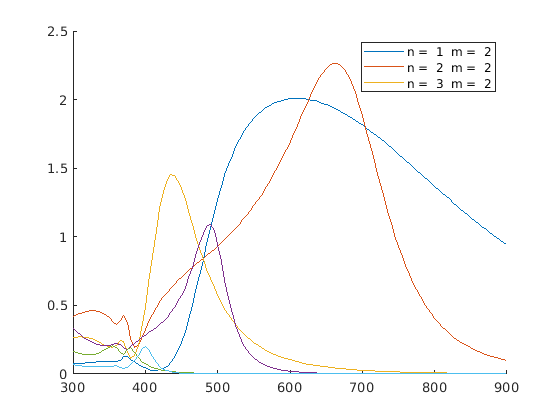



idx_cr = 1;
idx_ff = 1;

clearvars max_energy leg
figure, 
i = 1;
hold on 
for counter = 1:max_order*(max_order+1)
    [idxn, idxm] =ind2sub([max_order, max_order+1], counter);
    %max_energy = Astats.energy.max(:, :, idxn, idxm);
    max_energy = Astats.energy.max(:,:,idxn, idxm);
    if max_energy > 1e-1
        %plot(wavelengths, (squeeze(Astats.mean.mag(:, :,idxn, idxm))))
        x = (2*pi*140./wavelengths).';
        plot(wavelengths, 2.*(2*idxn+1).*(squeeze(Astats.mean.mag(:,:,idxn, idxm)))./(x.^2))
        plot(wavelengths, 2.*(2*idxn+1).*(squeeze(Bstats.mean.mag(:,:,idxn, idxm)))./(x.^2))
        leg{i} = strjoin({'n = ',num2str(idxn), ' m = ', num2str(idxm)}); 
        i = i+1;
    end
end
hold off  
legend(leg); 

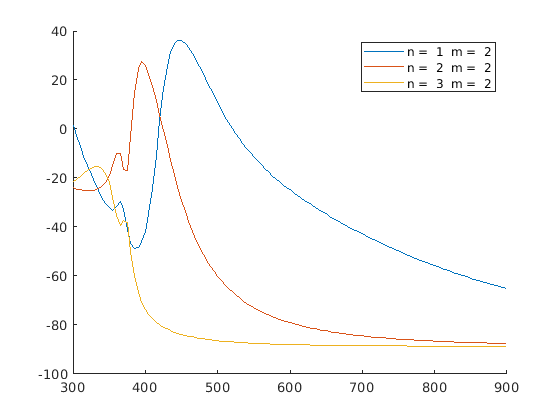

    
    
figure, 
i = 1;
hold on 
for counter = 1:max_order*(max_order+1)
    [idxn, idxm] =ind2sub([max_order, max_order+1], counter);
    %max_energy = Astats.energy.max(idx_cr, idx_ff, :, :, idxn, idxm);
    max_energy = Astats.energy.max(:,:, idxn, idxm);
    if max_energy > 1e-1
        %plot(wavelengths, (squeeze(Astats.mean.phase(idx_cr, idx_ff, :, :,idxn, idxm))))
        plot(wavelengths, (squeeze(Astats.mean.phase(:,:,idxn, idxm))))
        leg{i} = strjoin({'n = ',num2str(idxn), ' m = ', num2str(idxm)}); 
        i = i+1;
    end
end
hold off  
legend(leg); 